    
wellID = 1;

% PEDOT
ctrlFreshMediaDataPathPEDOT = '/home/mxwbio/Data/2025_08_01-JG-M231-PSD/250811/P003460/Record/000016/data.raw.h5';
cells72HrDataPathPEDOT = '/home/mxwbio/Data/2025_08_01-JG-M231-PSD/250811/P003460/Record/000023/data.raw.h5';

ctrlRawDataPEDOT = mxw.fileManager(ctrlFreshMediaDataPathPEDOT,wellID);
cellsRawDataPEDOT = mxw.fileManager(cells72HrDataPathPEDOT,wellID);

numSeconds = 0.5;
resolution = 2;

samplingFrequency = 20000;
startSample = 1;
highPassCutOff = 1;
bandwidth = [100 3500];
correctionFactor = 1;


ctrTablePEDOT = createSerialRecordingTable(ctrlRawDataPEDOT,startSample,numSeconds,correctionFactor,1);
ctrTablePEDOT = highPassFilterTraces(ctrTablePEDOT,highPassCutOff,samplingFrequency);
[ctrTablePEDOT, ctrlAvPSDPEDOT, ctrlAvfreqPEDOT] = calculatePSDs(ctrTablePEDOT,samplingFrequency,resolution);

[ctrlRMSPEDOT] = calculateAverageRMS(ctrlAvPSDPEDOT,ctrlAvfreqPEDOT,bandwidth,resolution);
disp(ctrlRMSPEDOT);

     1.754591494330649e-06




ctrTablePEDOT = calculateRMSs(ctrTablePEDOT, bandwidth,resolution);
ctrTablePEDOT = calculateResistances(ctrTablePEDOT, bandwidth);


nRecordingsPEDOT = cellsRawDataPEDOT.nRecordings;


cellsTableArrayPEDOT = cell(1,nRecordingsPEDOT);
cellsAvRMSArrayPEDOT = zeros(1,nRecordingsPEDOT);
cellsAvPSDArrayPEDOT = cell(1,nRecordingsPEDOT);
cellsAvDiffPSDArrayPEDOT = cell(1,nRecordingsPEDOT);
cellsAvFreqArrayPEDOT = cell(1,nRecordingsPEDOT);

i=1

i =      1



for recordingNum = 1:nRecordingsPEDOT

    cellsTableArrayPEDOT{i} = createSerialRecordingTable(cellsRawDataPEDOT,startSample,numSeconds,correctionFactor,recordingNum);

    cellsTableArrayPEDOT{i} = highPassFilterTraces(cellsTableArrayPEDOT{i},highPassCutOff,samplingFrequency);
    [cellsTableArrayPEDOT{i}, cellsAvPSDArrayPEDOT{i}, cellsAvFreqArrayPEDOT{i}] = calculatePSDs(cellsTableArrayPEDOT{i},samplingFrequency,resolution);

    [cellsTableArrayPEDOT{i},cellsAvDiffPSDArrayPEDOT{i}] = calculateDifferentialPSDs(cellsTableArrayPEDOT{i},ctrTablePEDOT);

    [cellsAvRMSArrayPEDOT(i)] = calculateAverageRMS(cellsAvDiffPSDArrayPEDOT{i},cellsAvFreqArrayPEDOT{i},bandwidth,resolution);
    disp(cellsAvRMSArrayPEDOT(i));

    cellsTableArrayPEDOT{i} = calculateDifferentialRMSs(cellsTableArrayPEDOT{i}, bandwidth,resolution);
    cellsTableArrayPEDOT{i} = calculateDifferentialResistances(cellsTableArrayPEDOT{i}, bandwidth);

    cellsTableArrayPEDOT{i} = calculateRMSs(cellsTableArrayPEDOT{i}, bandwidth,resolution);
    cellsTableArrayPEDOT{i} = calculateResistances(cellsTableArrayPEDOT{i}, bandwidth);

    cellsTableArrayPEDOT{i} = removevars(cellsTableArrayPEDOT{i},["rawTraces","filteredTraces",'PSDs','diffPSDs','frequencies']);

 
    i = i + 1;
end

     4.777247241133739e-07

     4.890885772073025e-07

     4.500495716736065e-07

     4.484500119211831e-07

     4.611844051756582e-07

     4.874189703545081e-07

     4.769732263916762e-07

     4.717572026053067e-07

     4.716562708597631e-07

     4.932398382571523e-07

     5.203453648257744e-07

     5.196841930075921e-07

     5.910807934841452e-07

     6.107412450465755e-07

     7.696293773755142e-07

     1.008938488192592e-06

     1.287221496780448e-06

     1.586843565372414e-06

     1.837414814141075e-06

     2.038925635286020e-06

     2.198568162358539e-06

     2.321816422098745e-06

     2.438212490128993e-06

     2.534700116758299e-06

     2.581759534124178e-06

     2.649827193696745e-06

     2.681233430704220e-06

     2.700558905331977e-06

     2.704451876890554e-06

     2.688385294592341e-06

     2.665378206157459e-06

     2.629172996761436e-06

     2.590184948137005e-06

     2.541858943009224e-06

     2.502171609783113e-06

     2.4488523368415


cellsAvPSDArrayPEDOT = cell2mat(cellsAvPSDArrayPEDOT);
cellsAvDiffPSDArrayPEDOT = cell2mat(cellsAvDiffPSDArrayPEDOT);
cellsAvFreqArrayPEDOT = cell2mat(cellsAvFreqArrayPEDOT);

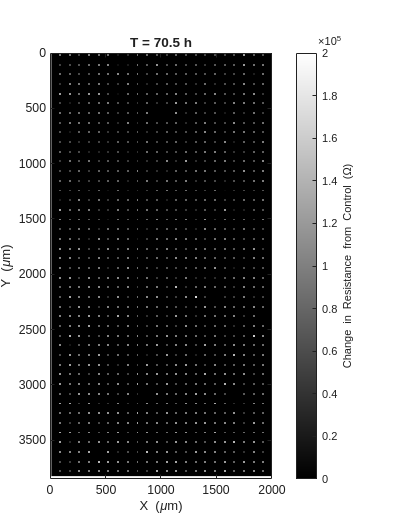

generateMEAVideo(nRecordingsPEDOT,cellsTableArrayPEDOT,'imagesc_sequence_pedot.avi');

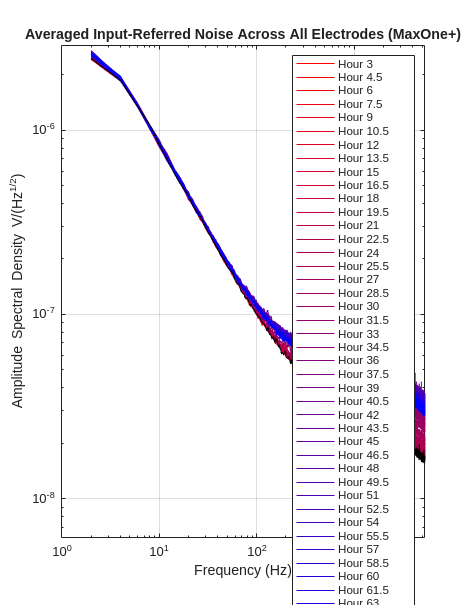

ylabelPlot = 'Amplitude Spectral Density V/(Hz^{1/2})';
titlePlot = 'Averaged Input-Referred Noise Across All Electrodes (MaxOne+)';
plotPowerSpectrum(cellsAvFreqArrayPEDOT,cellsAvPSDArrayPEDOT,ctrlAvfreqPEDOT,ctrlAvPSDPEDOT,nRecordingsPEDOT,67.5,titlePlot,ylabelPlot);

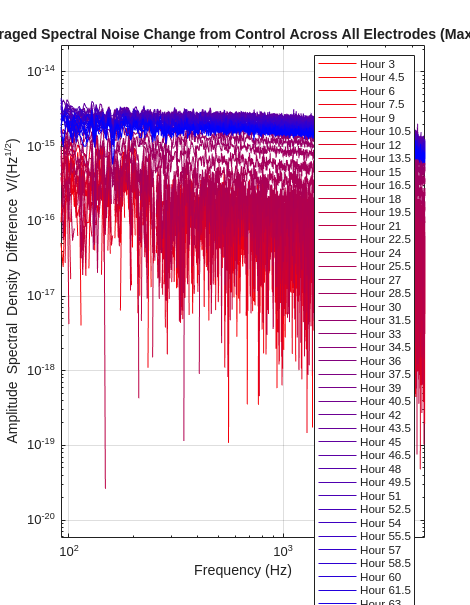

ylabelPlot = 'Amplitude Spectral Density Difference V/(Hz^{1/2})';
titlePlot = 'Averaged Spectral Noise Change from Control Across All Electrodes (MaxOne+)';
plotPowerSpectrumDiff(cellsAvFreqArrayPEDOT,cellsAvDiffPSDArrayPEDOT,nRecordingsPEDOT,67.5,titlePlot,ylabelPlot);

% Platinum
ctrlFreshMediaDataPathPt = '/home/mxwbio/Data/2025_08_01-JG-M231-PSD/250801/0022375/Record/000003/data.raw.h5';
cells72HrDataPathPt = '/home/mxwbio/Data/2025_08_01-JG-M231-PSD/250801/002375/Record/000009/data.raw.h5'

cells72HrDataPathPt = '/home/mxwbio/Data/2025_08_01-JG-M231-PSD/250801/002375/Record/000009/data.raw.h5'


ctrlRawDataPt = mxw.fileManager(ctrlFreshMediaDataPathPt,wellID);
cellsRawDataPt = mxw.fileManager(cells72HrDataPathPt,wellID);

numSeconds = 0.5;
resolution = 2;

samplingFrequency = 20000;
startSample = 1;
highPassCutOff = 1;
bandwidth = [100 3500];
correctionFactor = 1;


ctrTablePt = createSerialRecordingTable(ctrlRawDataPt,startSample,numSeconds,correctionFactor,1);
ctrTablePt = highPassFilterTraces(ctrTablePt,highPassCutOff,samplingFrequency);
[ctrTablePt, ctrlAvPSDPt, ctrlAvfreqPt] = calculatePSDs(ctrTablePt,samplingFrequency,resolution);

[ctrlRMSPt] = calculateAverageRMS(ctrlAvPSDPt,ctrlAvfreqPt,bandwidth,resolution);
disp(ctrlRMSPt);

     3.383322559209116e-06




ctrTablePt = calculateRMSs(ctrTablePt, bandwidth,resolution);
ctrTablePt = calculateResistances(ctrTablePt, bandwidth);


nRecordingsPt = cellsRawDataPt.nRecordings-1;


cellsTableArrayPt = cell(1,nRecordingsPt);
cellsAvRMSArrayPt = zeros(1,nRecordingsPt);
cellsAvPSDArrayPt = cell(1,nRecordingsPt);
cellsAvDiffPSDArrayPt = cell(1,nRecordingsPt);
cellsAvFreqArrayPt = cell(1,nRecordingsPt);

i=1

i =      1



for recordingNum = 1:nRecordingsPt

    cellsTableArrayPt{i} = createSerialRecordingTable(cellsRawDataPt,startSample,numSeconds,correctionFactor,recordingNum);

    cellsTableArrayPt{i} = highPassFilterTraces(cellsTableArrayPt{i},highPassCutOff,samplingFrequency);
    [cellsTableArrayPt{i}, cellsAvPSDArrayPt{i}, cellsAvFreqArrayPt{i}] = calculatePSDs(cellsTableArrayPt{i},samplingFrequency,resolution);

    [cellsTableArrayPt{i},cellsAvDiffPSDArrayPt{i}] = calculateDifferentialPSDs(cellsTableArrayPt{i},ctrTablePt);

    [cellsAvRMSArrayPt(i)] = calculateAverageRMS(cellsAvDiffPSDArrayPt{i},cellsAvFreqArrayPt{i},bandwidth,resolution);
    disp(cellsAvRMSArrayPt(i));

    cellsTableArrayPt{i} = calculateDifferentialRMSs(cellsTableArrayPt{i}, bandwidth,resolution);
    cellsTableArrayPt{i} = calculateDifferentialResistances(cellsTableArrayPt{i}, bandwidth);

    cellsTableArrayPt{i} = calculateRMSs(cellsTableArrayPt{i}, bandwidth,resolution);
    cellsTableArrayPt{i} = calculateResistances(cellsTableArrayPt{i}, bandwidth);

    cellsTableArrayPt{i} = removevars(cellsTableArrayPt{i},["rawTraces","filteredTraces",'PSDs','diffPSDs','frequencies']);

 
    i = i + 1;
end

     4.408170046519339e-07

      0.000000000000000e+00 + 4.839549866397196e-07i

      0.000000000000000e+00 + 3.000826390589901e-07i

     2.300925956122924e-07

      0.000000000000000e+00 + 6.228037634366612e-07i

     1.738639740670728e-07

      0.000000000000000e+00 + 1.835779582587177e-07i

      0.000000000000000e+00 + 6.012347660911115e-07i

      0.000000000000000e+00 + 4.652512742215507e-07i

      0.000000000000000e+00 + 6.263019002171125e-07i

      0.000000000000000e+00 + 5.491546286829833e-07i

      0.000000000000000e+00 + 4.725237136370136e-07i

      0.000000000000000e+00 + 4.873944780391589e-07i

     6.964277503904866e-08

     1.079266727682194e-07

     4.852531927712377e-07

     8.704646491208744e-07

     1.072464844142480e-06

     1.333802120934483e-06

     1.520095241595795e-06

     1.605703617969267e-06

     1.748510455607288e-06

     1.817099857171232e-06

     1.828850358494207e-06

     1.967863266337798e-06

     2.028237086746573e-06

     2.04780


cellsAvPSDArrayPt = cell2mat(cellsAvPSDArrayPt);
cellsAvDiffPSDArrayPt = cell2mat(cellsAvDiffPSDArrayPt);
cellsAvFreqArrayPt = cell2mat(cellsAvFreqArrayPt);

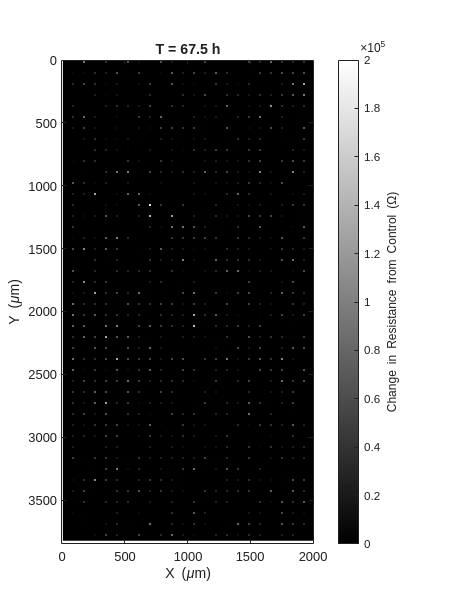

generateMEAVideo(nRecordingsPt,cellsTableArrayPt,'imagesc_sequence_pt.avi');

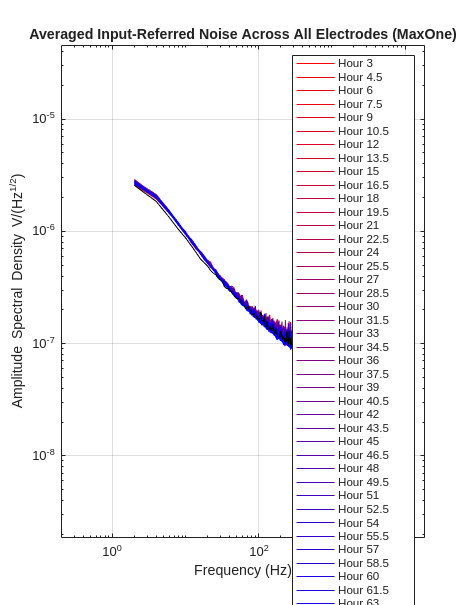

ylabelPlot = 'Amplitude Spectral Density V/(Hz^{1/2})';
titlePlot = 'Averaged Input-Referred Noise Across All Electrodes (MaxOne)';
plotPowerSpectrum(cellsAvFreqArrayPt,cellsAvPSDArrayPt,ctrlAvfreqPt,ctrlAvPSDPt,nRecordingsPt,64.5,titlePlot,ylabelPlot);

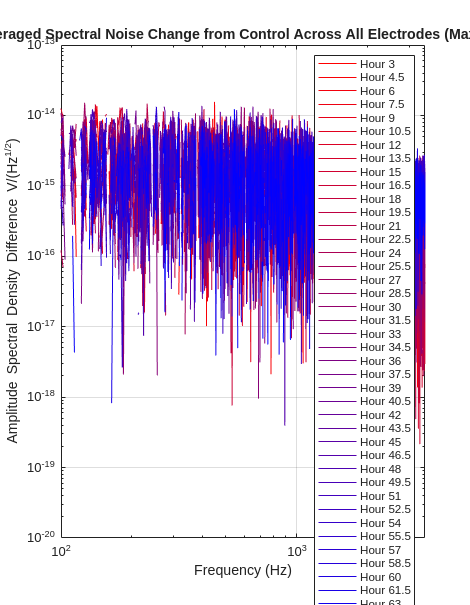

ylabelPlot = 'Amplitude Spectral Density Difference V/(Hz^{1/2})';
titlePlot = 'Averaged Spectral Noise Change from Control Across All Electrodes (MaxOne)';
plotPowerSpectrumDiff(cellsAvFreqArrayPt,cellsAvDiffPSDArrayPt,nRecordingsPt,64.5,titlePlot,ylabelPlot);

clf;

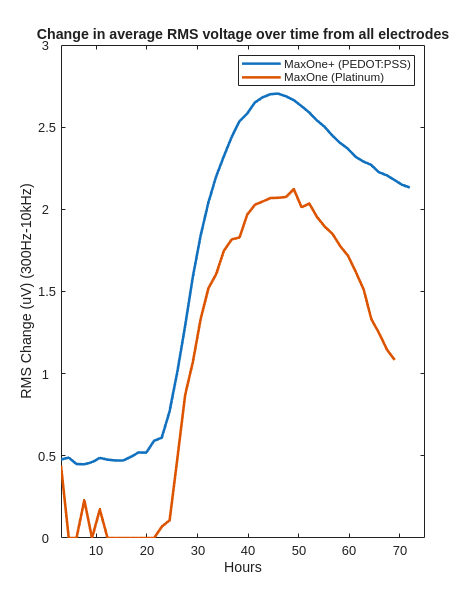

clear xlabel;
clear ylabel;


plot((linspace(0,46,46)*1.5+3),real(cellsAvRMSArrayPEDOT),LineWidth= 2);
hold on;
plot((linspace(0,44,44)*1.5+3),real(cellsAvRMSArrayPt),LineWidth= 2);
hold off;
ylim([0 3E-6]);
xlim([3 75]);

yt = get(gca,'YTick');
set(gca,'YTickLabel',yt*1E6);

xt = get(gca,'XTick');
set(gca,'XTickLabel',(xt));
xlabel('Hours');
ylabel('RMS Change (uV) (300Hz-10kHz)');
legend('MaxOne+ (PEDOT:PSS)','MaxOne (Platinum)');

title('Change in average RMS voltage over time from all electrodes');

function T = createSerialRecordingTable(rawData,startSample,numSeconds,correctionFactor,recordingNum)
        

        numSamples = numSeconds*rawData.fileObj(1).samplingFreq;
        [electrodeNums, xs,ys] = calculateXYCoords(rawData);
        
        rawTraces = zeros(length(electrodeNums),numSamples);
        hasTraces = false(length(electrodeNums),1);

        T = table(electrodeNums,hasTraces,xs,ys,rawTraces);
        
        [rawTracesInScan,~,electrodesInScan] = rawData.extractRawData(startSample,numSamples,'file',recordingNum);
        electrodesInScan = transpose(cell2mat(electrodesInScan));

        rawTracesInScan = transpose((rawTracesInScan./(1E6))*correctionFactor);
        [inTable, location] = ismember(T.electrodeNums, electrodesInScan);
        T.rawTraces(inTable,:) = rawTracesInScan(location(inTable),:);
        T.hasTraces(inTable) = true;
     
end

function T = createActivityScanTable(rawData,startSample,numSeconds,correctionFactor)
        

        numSamples = numSeconds*rawData.fileObj(1).samplingFreq;
        [electrodeNums, xs,ys] = calculateXYCoords(rawData);
        
        rawTraces = zeros(length(electrodeNums),numSamples);
        hasTraces = false(length(electrodeNums),1);

        T = table(electrodeNums,hasTraces,xs,ys,rawTraces);
        
        n = rawData.nRecordings;

        for recordingNum = 1:n
            [rawTracesInScan,~,electrodesInScan] = rawData.extractRawData(startSample,numSamples,'file',recordingNum);
            electrodesInScan = transpose(cell2mat(electrodesInScan));

            rawTracesInScan = transpose((rawTracesInScan./(1E6))*correctionFactor);
            [inTable, location] = ismember(T.electrodeNums, electrodesInScan);
            T.rawTraces(inTable,:) = rawTracesInScan(location(inTable),:);
            T.hasTraces(inTable) = true;

        end
     
end




function T = createFullElectrodeTable(rawData)

           [electrodeNums, xs, ys] = calculateXYCoords(rawData);
           
           T = table(electrodeNums,xs,ys);
 
end

function T = addSurfaceScanData(T,scanT)

    scanT = sortrows(scanT);
    scanT = scanT(scanT.Var2 > 0 & scanT.Var2 <= 100,:);
    T = addvars(T,scanT.Var2,'NewVariableNames','surfaceScanVals');

end

function T = calculateDifferentialSurfaceScanData(T,scanT)

    scanT = sortrows(scanT);
    scanT = scanT(scanT.Var2 > 0 & scanT.Var2 <= 100,:);
    diffVals = T.surfaceScanVals - scanT.Var2;

    T = addvars(T,diffVals,'NewVariableNames','diffSurfaceScanVals');

end

    
function T = highPassFilterTraces(T, highPassCutOff,samplingFreq)
        
        [sos,g] = butter(1,highPassCutOff/(samplingFreq/2),"high");
        filteredTraces = filtfilt(sos,g,double(transpose(T.rawTraces)));
        T = addvars(T,transpose(filteredTraces),'NewVariableNames','filteredTraces');
        
end

function [T, avPSD, avFreq] = calculatePSDs(T,samplingFreq,resolution)
    
        

        overlap = 0;    
        nfft = samplingFreq / resolution;
        window = hann(nfft);

        [PSDs,frequencies] = pwelch(transpose(T.filteredTraces),window,overlap,nfft,samplingFreq);
        
        
        avPSD = sum(PSDs,2)/(sum(T.hasTraces)); 

        avFreq = frequencies;

        frequencies = repmat(frequencies,1,size(PSDs,2));
        PSDs = transpose(PSDs);
        frequencies = transpose(frequencies);

        T = addvars(T,PSDs,frequencies,'NewVariableNames',{'PSDs', 'frequencies'});  
        
end

function [T, avPSD, avFreq] = calculateSubsetPSDs(T,samplingFreq,resolution,numElectrodes)

        overlap = 0;    
        nfft = samplingFreq / resolution;
        window = hann(nfft);

        PSDs = zeros(height(T),((nfft/2)+1));
        frequencies = zeros(height(T),((nfft/2)+1));

        T = addvars(T,PSDs,frequencies,'NewVariableNames',{'PSDs', 'frequencies'});  

        electrodesCount = 0;
    
        for i=1:height(T)
            if (T.hasTraces(i)) && (electrodesCount <= numElectrodes)

                [T.PSDs(i,:),T.frequencies(i,:)] = pwelch(T.filteredTraces(i,:),window,overlap,nfft,samplingFreq);
                electrodesCount = electrodesCount + 1;
                frequencies = T.frequencies(i,:);
            end
        end

        avPSD = sum(T.PSDs,1)/numElectrodes; 

        avFreq = frequencies;

end




function [T,avDiffPSD] = calculateDifferentialPSDs (T,controlT)

        differentialPSDs = transpose(T.PSDs) - transpose(controlT.PSDs);

        avDiffPSD = sum(differentialPSDs,2)/sum(T.hasTraces);

        T = addvars(T, transpose(differentialPSDs), 'NewVariableNames','diffPSDs');
    
end

function avRMS = calculateAverageRMS(avPSD,avFreq,bandwidth, resolution)

        

        bandwidth = bandwidth./resolution;
        f = avFreq(bandwidth(1):bandwidth(2));
        PSD = avPSD(bandwidth(1):bandwidth(2));

        avRMS = sqrt(trapz(f,PSD));

end




function T = calculateRMSs(T,bandwidth,resolution)

        bandwidth = bandwidth./resolution;
        len = height(T);
        RMSs = zeros(len, 1);
        variances = zeros(len, 1);

        for i = 1:len
            f = transpose(T.frequencies(i,bandwidth(1):bandwidth(2)));
            PSD = transpose(T.PSDs(i,bandwidth(1):bandwidth(2)));
            RMSs(i) = sqrt(trapz(f,PSD)); 
            variances(i) = trapz(f,PSD); 
        end

        T = addvars(T, RMSs,variances,'NewVariableNames',{'RMSs','variances'});

end

function T = calculateDifferentialRMSs(T,bandwidth,resolution)

        bandwidth = bandwidth./resolution;
        len = height(T);
        diffVariances = zeros(len, 1);
        diffRMSs = zeros(len, 1);

        for i = 1:len
            f = transpose(T.frequencies(i,bandwidth(1):bandwidth(2)));
            diffPSD = transpose(T.diffPSDs(i,bandwidth(1):bandwidth(2)));
            diffRMSs(i) = sqrt(trapz(f,diffPSD)); 
            diffVariances(i) = trapz(f,diffPSD); 
        end

        T = addvars(T, diffRMSs,diffVariances, 'NewVariableNames',{'diffRMSs','diffVariances'});

end

function T = calculateResistances (T,bandwidth)
        
        boltzman = 1.38E-23;
        temp = 310;

        resistances = (transpose(T.variances))./(4*boltzman*temp*(bandwidth(2)-bandwidth(1)));
        T = addvars(T, transpose(resistances), 'NewVariableNames','resistances');

end


function T = calculateDifferentialResistances (T,bandwidth)
        
        boltzman = 1.38E-23;
        temp = 310;

        diffResistances = (transpose(T.diffVariances))./(4*boltzman*temp*(bandwidth(2)-bandwidth(1)));
        T = addvars(T, transpose(diffResistances), 'NewVariableNames','diffResistances');

end

function [electrodeNums, xs, ys] = calculateXYCoords(rawData)

        recordingElectrodes = rawData.processedMap.electrode();
        unroutedElectrodes = rawData.processedMap.nonRoutedElec();

        electrodeNums = cat(1,recordingElectrodes,unroutedElectrodes);
        electrodeNums = sort(electrodeNums);
        
        len = length(electrodeNums);
        
        xs = zeros(1,len);
        ys = zeros(1,len);
        
        for i = 1:len
            ys(i) = ceil(i/220) ;
            xs(i) = i - (220*(ys(i)-1));
            
        end

        W = 220; 

        x_rot = ys;
        y_rot = (W - 1) - xs;

        xs = x_rot;
        ys = y_rot;

       
        
        xs = transpose(xs*17.5);
        ys = transpose(ys*17.5);
end

function plotPowerSpectrum(cellsAvFreqArray,cellsAvPSDArray,tAvfreq,tAvPSD,nRecordings,endRecording,titlePlot,ylabelPlot)
        clf('reset');
        
        loglog(cellsAvFreqArray,sqrt(cellsAvPSDArray));
        hold on;
        loglog(tAvfreq,sqrt(tAvPSD));
        hold off;
        
        colorMapLength = nRecordings;
        red = [1,0,0];
        blue = [0,0,1];
        black = [0,0,0];
        
        
        colours_scale = [linspace(red(1),blue(1),colorMapLength)', linspace(red(2),blue(2),colorMapLength)', linspace(red(3),blue(3),colorMapLength)'];
        colours_ctrl = black;
        ax=gca;
        ax.ColorOrder = cat(1,colours_scale,colours_ctrl);
        
        hours = linspace(0,endRecording,nRecordings)+3;
        legendText = cell(1,nRecordings+1);
        
        for i = 1:nRecordings
            legendText{i} = sprintf('Hour %g ',hours(i));
        end
        
        mediaLabel = 'Media Control';
        legendText{nRecordings+1} = mediaLabel;
        legend(string(transpose(legendText)))
        
        xlim([0 5000]);
        xlabel('Frequency (Hz)');
        ylabel(ylabelPlot);
        title(titlePlot);
        set(gca,'xminorgrid','off','yminorgrid','off','xgrid','on','ygrid','on')
end

function plotPowerSpectrumDiff(cellsAvFreqArray,cellsAvPSDArray,nRecordings,endRecording,titlePlot,ylabelPlot)
        clf('reset');
        
        loglog(cellsAvFreqArray,cellsAvPSDArray);
        
        
        colorMapLength = nRecordings;
        red = [1,0,0];
        blue = [0,0,1];
        black = [0,0,0];
        
        
        colours_scale = [linspace(red(1),blue(1),colorMapLength)', linspace(red(2),blue(2),colorMapLength)', linspace(red(3),blue(3),colorMapLength)'];
        colours_ctrl = black;
        ax=gca;
        ax.ColorOrder = cat(1,colours_scale,colours_ctrl);
        
        hours = linspace(0,endRecording,nRecordings)+3;
        legendText = cell(1,nRecordings);
        
        for i = 1:nRecordings
            legendText{i} = sprintf('Hour %g ',hours(i));
        end
        
     
        legend(string(transpose(legendText)))
        
        xlim([100 3500]);
        xlabel('Frequency (Hz)');
        ylabel(ylabelPlot);
        title(titlePlot);
        set(gca,'xminorgrid','off','yminorgrid','off','xgrid','on','ygrid','on')
end

function generateMEAVideo(nRecordings,cellsTableArray,filename)
        videoFile = filename;
        
        v = VideoWriter(videoFile, 'Uncompressed AVI');
        v.FrameRate = 2;         
        open(v);
        
        figure;
        set(gcf,'Position',[100 100 700 900], 'Color','w');              
        ax = axes('Position',[0.1 0.1 0.75 0.8]);
        
        
        hours = 1.5;          
        
        for i = 1:nRecordings
        
            cla(ax);
        
            Z = reshape(transpose(cellsTableArray{i}.diffResistances),220,120);
        
            imagesc(ax,cellsTableArray{i}.xs,cellsTableArray{i}.ys,Z);
        
            axis(ax,'equal');
            axis(ax,[0 2000 0 3850]);
            colormap(ax,gray);
            clim(ax,[0 200e3]);
        
            xlabel(ax,'X (\mum)');
            ylabel(ax,'Y (\mum)');
                 
            cb = colorbar(ax);
            cb.Label.String = 'Change in Resistance from Control (\Omega)';
            cb.Location = 'eastoutside';
            
            t_hours = (i-1) * hours + 3;
            title(ax, sprintf('T = %.1f h', t_hours),'FontWeight','bold')
        
            drawnow        
            frame = getframe(gcf);
            writeVideo(v, frame);
        end
        
        close(v);
end